Hausübung 1

Autor: Stefa Kolb

Personenkennzahl: 1910414015

Matrikelnummer: 01011450

Erzeuge Signal:


$$f\left(t\right)=\left(10\cdot \cos \left(2\pi \left(5t\right)\right)+5\cdot \cos \left(2\pi \left(40t\right)\right)\right)\cdot e^{-\pi t^2 }$$


mit $t\in \left\lbrack -\mathrm{tWindow},+\mathrm{tWindow}\right\rbrack$

Single-sided

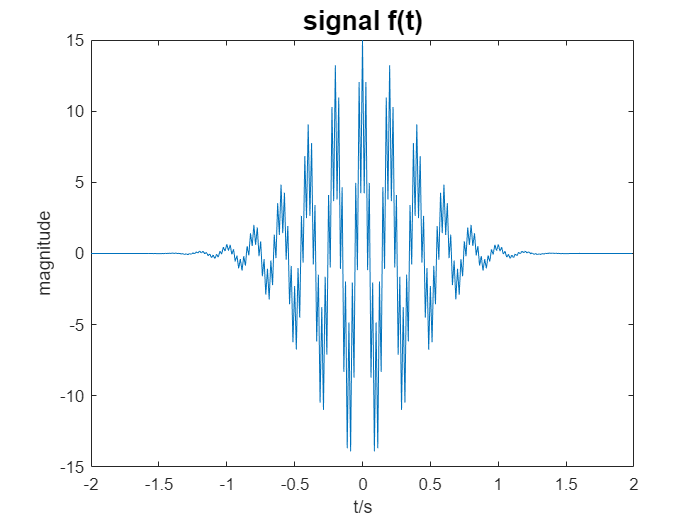

tWindow = 2;
v = [5,40]; % signal frequencies
Fs = 2*max(v); % nyquist frequency
step = 1/Fs;

% time vector
t = -tWindow:step:tWindow;

% truncates if number of entries odd
if(mod(length(t),2))
    t = t(1:end-1);
end

% signal
sig = (10*cos(2*pi*(v(1)*t)) +5*cos(2*pi*(v(2)*t))).*exp(-pi*t.^2);

% show f(t)
figure;
plot(t,sig,'LineWidth',0.1)
xlabel('t/s')
ylabel('magnitude')
title('signal f(t)','FontSize',16)

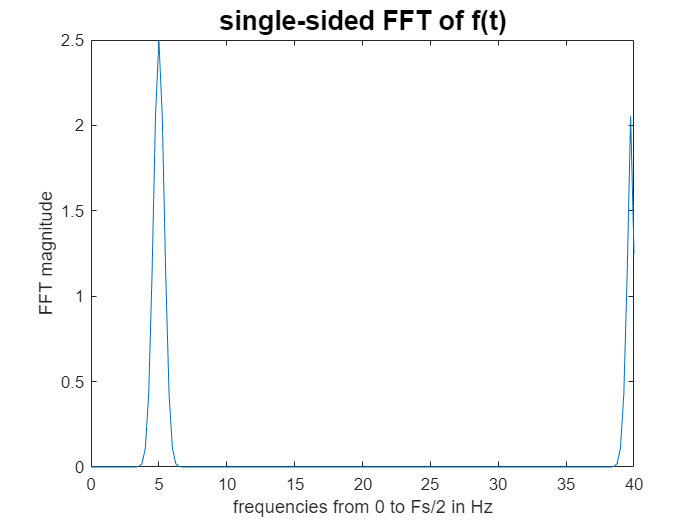


Y = fft(sig); % Fourier transform

L = length(Y);
P2 = abs(Y/L); % double-sided FFT

% single-sided FFT
P1 = P2(1:(L/2)+1);
P1(2:end-1)=2*P1(2:end-1);

% frequency vector
f = Fs*(0:(L/2))/L;

% show FFT of f(t)
figure;
plot(f,P1,'LineWidth',0.1)
xlabel('frequencies from 0 to Fs/2 in Hz')
ylabel('FFT magnitude')
title('single-sided FFT of f(t)','FontSize',16)


% sum over peaks
disp(['sum over peaks = ' num2str(sum(P1))])

sum over peaks = 15


double-sided 

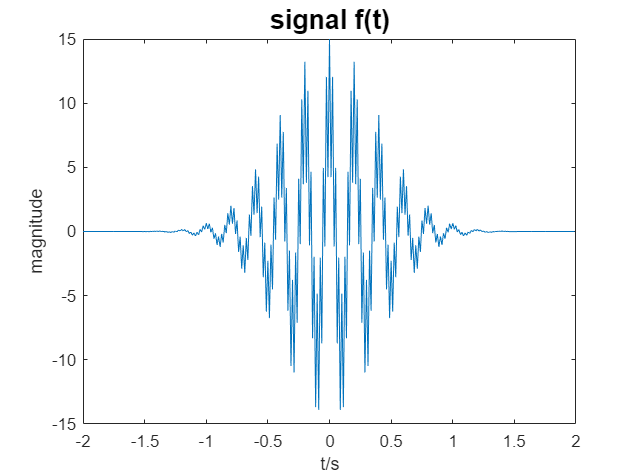

tWindow = 2;
v = [5,40]; % signal frequencies
Fs = 2*max(v); % nyquist frequency
step = 1/Fs;

% time vector
t = -tWindow:step:tWindow;

% truncates if number of entries odd
if(mod(length(t),2))
    t = t(1:end-1);
end

% signal
sig = (10*cos(2*pi*(v(1)*t)) +5*cos(2*pi*(v(2)*t))).*exp(-pi*t.^2);

% show f(t)
figure;
plot(t,sig,'LineWidth',0.1)
xlabel('t/s')
ylabel('magnitude')
title('signal f(t)','FontSize',16)

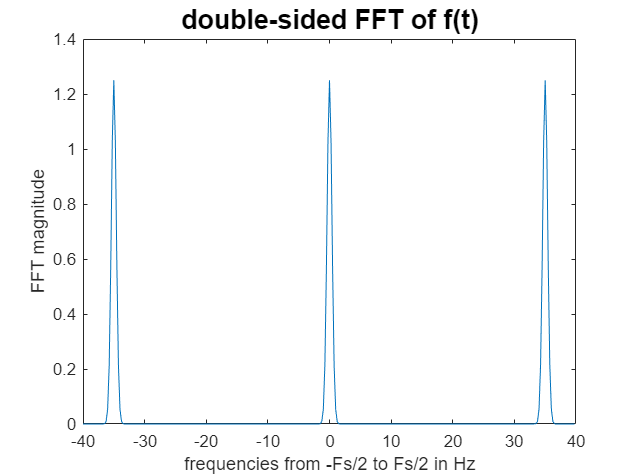


Y = fft(sig); % Fourier transform

L = length(Y);
P2 = abs(Y/L); % double-sided FFT

% frequency vector
f = Fs*((-L/2):(L/2-1))/L;

% show FFT of f(t)
figure;
plot(f,P2,'LineWidth',0.1)
xlabel('frequencies from -Fs/2 to Fs/2 in Hz')
ylabel('FFT magnitude')
title('double-sided FFT of f(t)','FontSize',16)


% sum over peaks
disp(['sum over peaks = ' num2str(sum(P2))])

sum over peaks = 15
